# **Runge-Kutta 4th Order**

## 
$$\begin{array}{l}
y_{n+1} =y_n +\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)\\
k_1 =h\cdot f\left(x_n ,y_n \right)\\
k_2 =h\cdot f\left(x_n +\frac{h}{2},y_{n\;} +\frac{k_1 }{2}\right)\\
k_3 =h\cdot f\left(x_n +\frac{h}{2\;},y_{n\;} +\frac{k_2 }{2}\right)\\
k_4 =h\cdot f\left(x_n +h,y_n +k_3 \right)
\end{array}$$


clear all;
format long;

% params
f = @(x, y) 3*(x^2)*exp(x)-y;
y(1) = 1;
xn = 5;
x0 = 0;
h = 0.2;

% function
x = x0:h:xn;

for n = 1:length(x)-1
    k1 = h * f(x(n), y(n));
    k2 = h * f(x(n)+h/2, y(n)+k1/2);
    k3 = h * f(x(n)+h/2, y(n)+k2/2);
    k4 = h * f(x(n)+h, y(n)+k3);
    y(n+1) = y(n) + (1/6)*(k1 + 2*k2 + 2*k3 +k4);
    fprintf('Approximate value of y(%f) = %f\n', x(n+1), y(n+1))
end

Approximate value of y(0.200000) = 0.827620
Approximate value of y(0.400000) = 0.749444
Approximate value of y(0.600000) = 0.847925
Approximate value of y(0.800000) = 1.247516
Approximate value of y(1.000000) = 2.130928
Approximate value of y(1.200000) = 3.760999
Approximate value of y(1.400000) = 6.509960
Approximate value of y(1.600000) = 10.898395
Approximate value of y(1.800000) = 17.646904
Approximate value of y(2.000000) = 27.744342
Approximate value of y(2.200000) = 42.537660
Approximate value of y(2.400000) = 63.849821
Approximate value of y(2.600000) = 94.134124
Approximate value of y(2.800000) = 136.675679
Approximate value of y(3.000000) = 195.853798
Approximate value of y(3.200000) = 277.482993
Approximate value of y(3.400000) = 389.255211
Approximate value of y(3.600000) = 541.312293
Approximate value of y(3.800000) = 746.985683
Approximate value of y(4.000000) = 1023.750673
Approximate value of y(4.200000) = 1394.455472
Approximate value of y(4.400000) = 1888.901959
Appro

plot(x, y, '*-', 'LineWidth', 1.3);
hold on;
soln = dsolve('Dy = 3*(x^2)*exp(x)-y', 'y(0)=1', 'x')

$$soln = \frac{{\mathrm{e}}^{-x}}{4}+\frac{3\,{\mathrm{e}}^{x}\,\left(4\,x^{2}-4\,x+2\right)}{8}$$

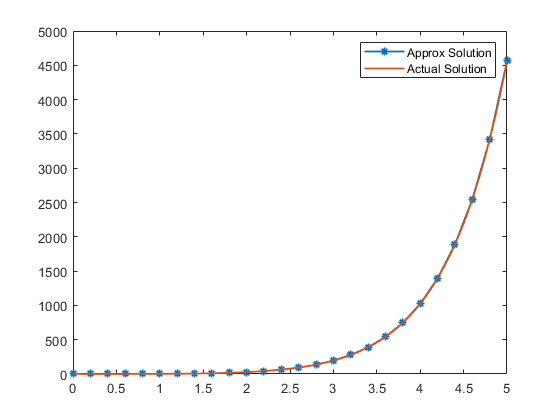

xt = x0:0.01:xn;
yt = subs(soln, xt);
plot(xt, yt, 'LineWidth', 1.3);
hold off;
legend('Approx Solution', 'Actual Solution')

clear all;
format long;

% params
f = @(x, y) x.^2 + y.^2;
y(1) = 1;
xn = 1;
x0 = 0;
h = 0.2;

% function
x = x0:h:xn;

for n = 1:length(x)-1
    k1 = h * f(x(n), y(n));
    k2 = h * f(x(n)+h/2, y(n)+k1/2);
    k3 = h * f(x(n)+h/2, y(n)+k2/2);
    k4 = h * f(x(n)+h, y(n)+k3);
    y(n+1) = y(n) + (1/6)*(k1 + 2*k2 + 2*k3 +k4);
    fprintf('Approximate value of y(%f) = %f\n', x(n+1), y(n+1))
end

Approximate value of y(0.200000) = 1.252991
Approximate value of y(0.400000) = 1.695920
Approximate value of y(0.600000) = 2.642110
Approximate value of y(0.800000) = 5.785463
Approximate value of y(1.000000) = 99.965347


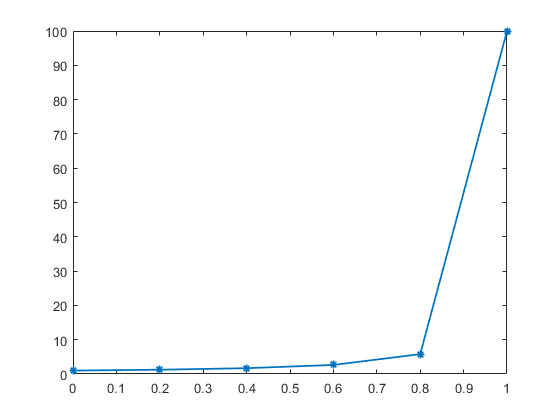

plot(x, y, '*-', 'LineWidth', 1.3);

hold on;
soln = dsolve('Dy = 3*(x^2)*exp(x)-y', 'y(0)=1', 'x')
xt = x0:0.01:xn;
yt = subs(soln, xt);
plot(xt, yt, 'LineWidth', 1.3);
hold off;
legend('Approx Solution', 'Actual Solution')